# Analysis of collagen SHG image

Load and display the image

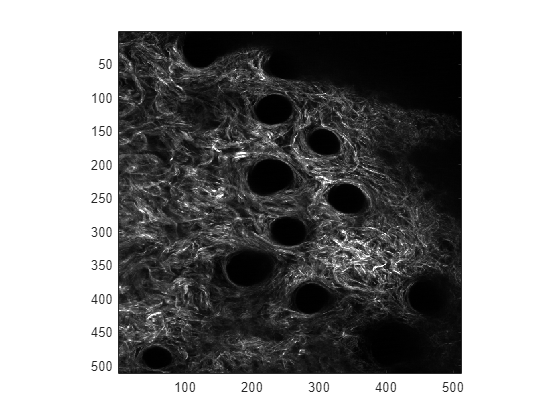

shgim = imread('./documentation/calcfibang2D/SHG Intensity Image.tif');
figure; imagesc(shgim); colormap gray;
axis image;

Calculate the pixel-wise intensity-based fiber orientation with a kernel size of 7 pixels and no filtering

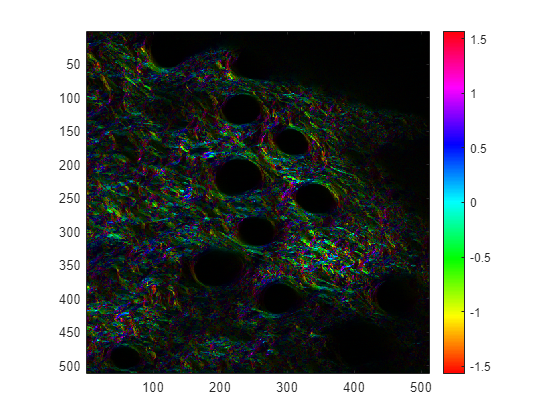

orientImg = calcfibang2D(shgim,7,0);
figure; imagesc(orientImg,'AlphaData',single(shgim)./8191); colormap hsv;
caxis([-pi/2 pi/2]); % Adjust color limits (if necessary)
axis image; colorbar;
set(gca,'Color',[0 0 0]); % Set background color to black

Create a simple collagen-positive mask based on the intensity

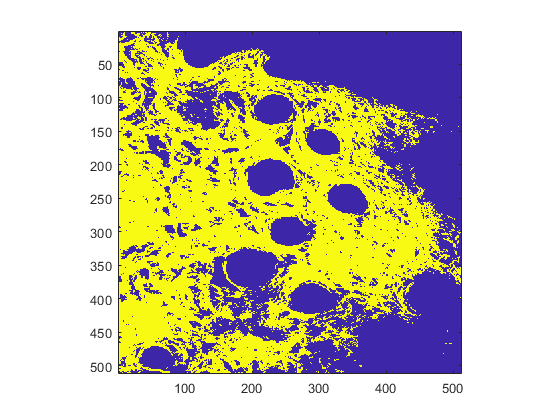

shgMask = (shgim > 1000);
figure; imagesc(shgMask);
axis image;

Calculate a map of local directional variance with an 21 x 21 pixel square

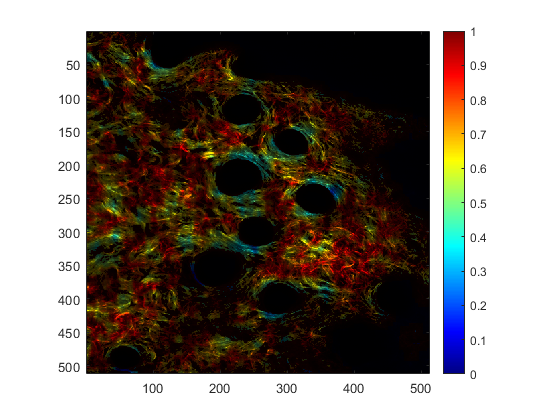

dv = directionalVariance2D(orientImg,shgMask,21);
% Display local DV map
figure; imagesc(dv,'AlphaData',single(shgim)./8191); colormap jet;
caxis([0 1])
axis image; colorbar;
set(gca,'Color',[0 0 0]);